% paths
addpath(path)
path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared"

path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared"

cd(path2)
addpath(genpath('utils')); % all folders in utils added, including semedo code

% load
load("Megatable.mat");

% query
key = "326c076";
%key = "0d8dd75"
queryresult = [];

numToExamine = size(TABLE,1);
for i = 1:numToExamine
    fileTable = table2array(TABLE(i,"Filetable"));
    if fileTable.hash == key
        queryresult = TABLE(i,:);
    end
end

if isempty(queryresult)
    warning("the key does not exist");
end

Figure 2A: Cofiring in source and target

Figure 2B: Prediction Performance

Figure 4A/B: Results from rank regress

Figure 4C: How optimal number of predicitive dimensions compare between hpc and pfc

% basic structures and stats
Patterns = table2array(queryresult(1,"Patterntable"));
Patterns = reshape(table2array(Patterns), [10,2,4]);

[nPartitions, nDirections, nPatterns] = size(Patterns);
nPatterns = nPatterns-1; % single control

Options = table2array(queryresult(1,"Optiontable"));
nSource = size(Patterns(10,2,1).X_source,1);
nTarget = size(Patterns(10,2,1).X_target,1);
patternnames = ["theta", "delta", "ripples"];

## Figure 2

#### A: How pairs of neuron in source/target co-fire

load("cofiring.mat");

numPairsPerPattern = (nSource+nTarget)^2 - nSource^2 - nTarget^2;

hp_pairs_patterns = zeros(nPatterns, numPairsPerPattern);
hh_pairs_patterns = zeros(nPatterns, numPairsPerPattern);

all_pairs_across_regions = [];
all_pairs_within_hpc = [];

mean_hpcorr = [];
mean_hhcorr = [];

std_hhcorr = [];
std_hpcorr = [];

for p = 1:10
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        curr_HPC = Patterns(p,1,i).X_target';
        curr_PFC = Patterns(p,2,i).X_target';
        
        linearized_hh = plots.calculatePatternCofiring(curr_source, curr_HPC);
        linearized_hp = plots.calculatePatternCofiring(curr_source, curr_PFC);
        
        all_pairs_within_hpc = [all_pairs_within_hpc, linearized_hh];
        all_pairs_across_regions = [all_pairs_across_regions, linearized_hp];
        
        hp_pairs_patterns(i,:) = linearized_hp;
        hh_pairs_patterns(i,:) = linearized_hh;
    end
    cur_mean_hhcorr = mean(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
    cur_std_hhcorr = std(all_pairs_within_hpc(~isnan(all_pairs_within_hpc)));
    
    cur_mean_hpcorr = mean(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
    cur_std_hpcorr = std(all_pairs_across_regions(~isnan(all_pairs_across_regions)));
    
    mean_hhcorr = [mean_hhcorr, cur_mean_hhcorr];
    mean_hpcorr = [mean_hpcorr, cur_mean_hpcorr];
    
    std_hhcorr = [std_hhcorr, cur_mean_hhcorr];
    std_hpcorr = [std_hpcorr, cur_mean_hpcorr];
    
end


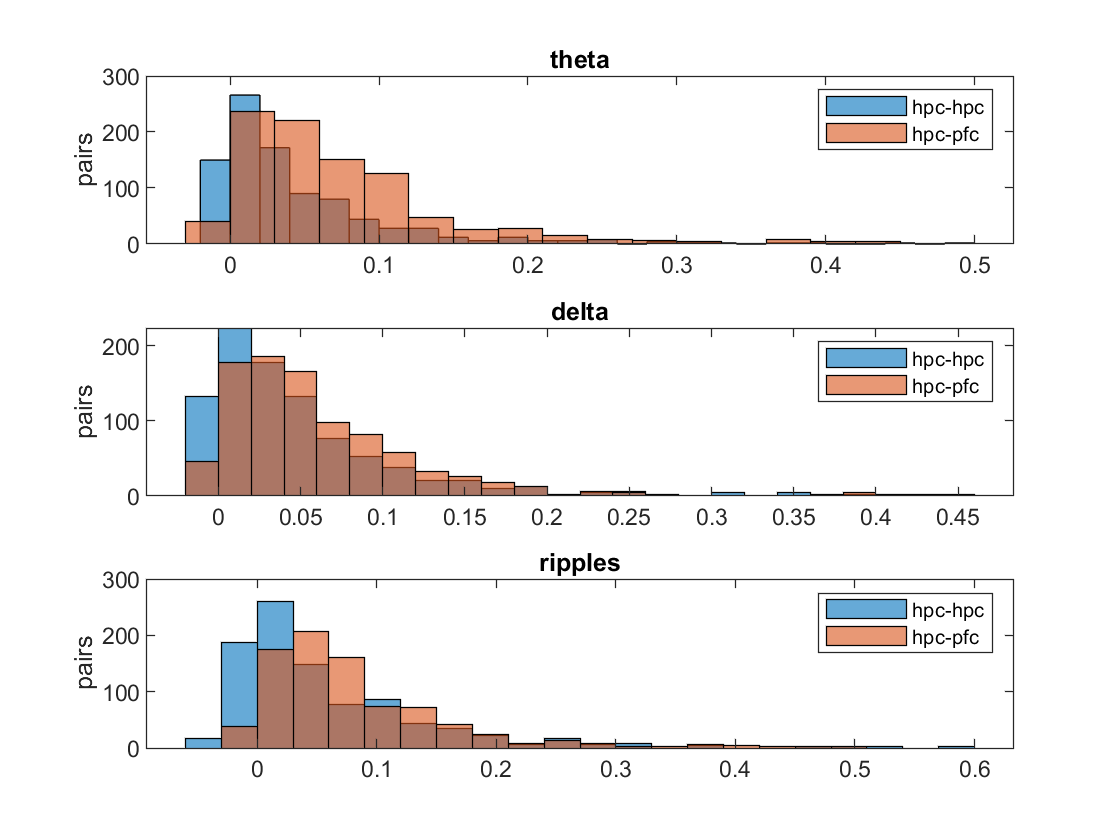

figure(499)
clf
for i = 1:nPatterns
    subplot(3,1,i)
    histogram(hh_pairs_patterns(i,:));
    hold on
    histogram(hp_pairs_patterns(i,:));
    legend("hpc-hpc","hpc-pfc")
    title(patternnames(i))
    ylabel("pairs")
end


figure (500)
subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(all_pairs_within_hpc)

hist_hh =   Histogram with properties:

             Data: [1×27720 double]
           Values: [8 124 270 830 3442 3848 3114 2668 2096 1566 1468 1314 1008 852 632 648 522 388 282 386 228 210 168 218 152 190 68 46 66 120 110 34 64 30 54 46 62 28 32 56 28 38 18 0 42 26 8 22 0 8 8 10 0 12 10 0 0 0 10 0 10 0 0 22]
          NumBins: 64
         BinEdges: [1×65 double]
         BinWidth: 0.0100
        BinLimits: [-0.0500 0.5900]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


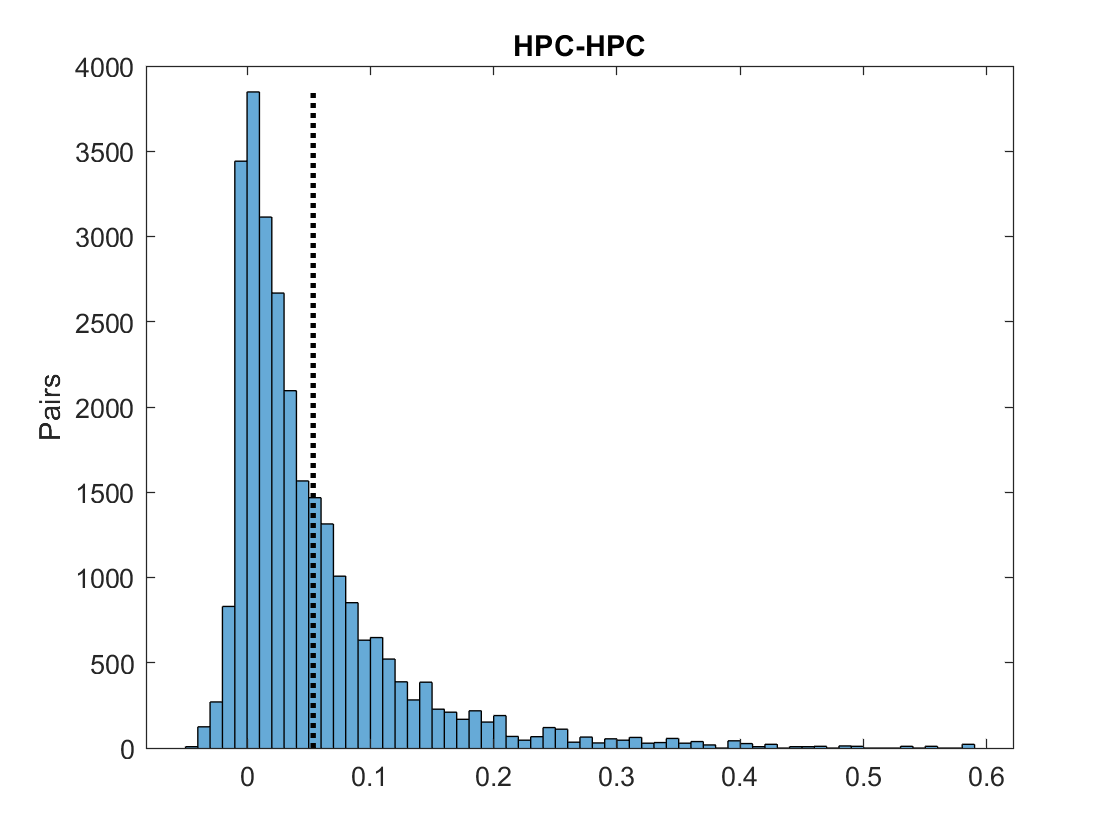

ylabel("Pairs")
title ("HPC-HPC")
example_mean_hhcorr = mean_hhcorr(1);
example_std_hhcorr = std_hhcorr(1);

hold on
lineObject=line([example_mean_hhcorr,example_mean_hhcorr],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(all_pairs_across_regions)

hist_hp =   Histogram with properties:

             Data: [1×27720 double]
           Values: [6 6 130 378 1488 2284 2314 2476 2524 2370 2050 1582 1472 1374 1310 834 828 570 480 390 366 372 178 212 226 140 126 90 76 110 38 80 60 40 24 30 10 22 32 14 14 62 50 50 18 14 10 8 14 6 0 10 2 0 4 6 0 0 0 0 0 4]
          NumBins: 62
         BinEdges: [1×63 double]
         BinWidth: 0.0100
        BinLimits: [-0.0500 0.5700]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


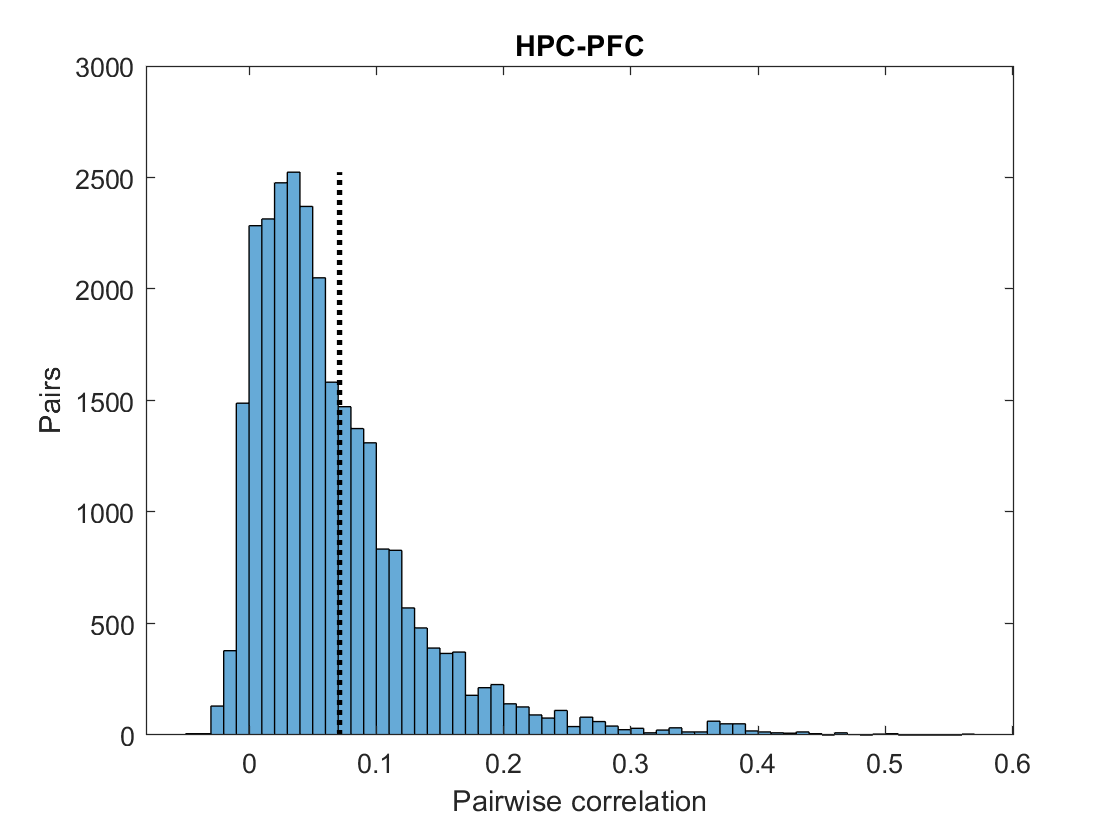

ylabel("Pairs")
title ("HPC-PFC")
example_mean_hpcorr = mean_hpcorr(1);
example_std_hpcorr = std_hpcorr(1);

lineObject=line([example_mean_hpcorr,example_mean_hpcorr],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
xlabel("Pairwise correlation")
linkaxes([ax1,ax2],'x');

[h_corrdiff,p_corrdiff] = kstest2(all_pairs_across_regions,all_pairs_within_hpc);

% saving meaningful stats and the corresponding Option fields in a csv
Resulttable = table(mean(mean_hhcorr), mean(std_hhcorr), mean(mean_hpcorr), mean(std_hpcorr), h_corrdiff, p_corrdiff)
cofiringRow = table(Options,Resulttable, key);

%cofiringstats = [cofiringstats, cofiringRow];
% cofiringstats.cofiringRow = [cofiringstats.cofiringRow; table(Optiontable, Resulttable)];
save('cofiring', 'cofiringstats')

% print stats
formatSpec1 = "%s: %0.3f±%0.3f";

sprintf(formatSpec1,Patterns(1,1).directionality,mean(mean_hhcorr),mean(std_hhcorr))

ans = "hpc-hpc: 0.048±0.048"

sprintf(formatSpec1,Patterns(2,1).directionality,mean(mean_hpcorr),mean(std_hpcorr))

ans = "hpc-hpc: 0.035±0.035"

disp(p_corrdiff)

  6.2764e-167



Average correlation:

HPC-HPC: 0.1413 ± 0.1047

HPC-PFC: 0.0397 ± 0.0509

p < 0.01 for difference between HPC-PFC and HPC-HPC.

*"These weak correlations indicate that only a small fraction of a neuron’s response variability*

*can be explained by another individual neuron"*

#### B: Prediction Performance

load("prediction.mat");
figure(600), clf
% how well a single neuron can predict stuff
all_single_prediction_hh = [];
all_single_prediction_hp = [];

patternPerformance_pfc = zeros(nPatterns, nPartitions); % prediction of
patternPerformance_hpc = zeros(nPatterns, nPartitions);
useSinglePrediction = true;
for p = 1:nPartitions
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        nSource = size(curr_source,2);
        for d = 1:2
            curr_target = Patterns(p,d,i).X_target';
            for k = 1:nSource
                curr_singleB = Patterns(p,d,i).rankRegress.singlesource_B{k};
                if ~isempty(curr_singleB)
                    curr_singlesource = curr_source(:,k);
                    [singlepattern,~] = plots.calculatePredictionPerformance(curr_singlesource, curr_target, curr_singleB);
                    if d == 1
                        [all_single_prediction_hh] = [all_single_prediction_hh singlepattern];
                    else
                        [all_single_prediction_hp] = [all_single_prediction_hp singlepattern];
                    end
                end
            end
        end
    end
end
median_singlehh = median(all_single_prediction_hh(~isnan(all_single_prediction_hh)));
temp1 = all_single_prediction_hp(~isinf(all_single_prediction_hp));
temp1 = temp1(~isnan(temp1));
median_singlehp = median(temp1);


r_square_hh = [];
r_square_hp = [];

r_square_hh_patterns = zeros(nPatterns, nTarget*nPartitions);
r_square_hp_patterns = zeros(nPatterns, nTarget*nPartitions);

for p = 1:10
    for i = 1:nPatterns
        curr_source = (Patterns(p,1,i).X_source)';
        curr_targethpc = (Patterns(p,1,i).X_target)';
        curr_targetpfc = (Patterns(p,2,i).X_target)';
        
        curr_B_hpc = Patterns(p,1,i).rankRegress.B;
        curr_B_pfc = Patterns(p,2,i).rankRegress.B;
        
        [patternhpc, meanhpc] = plots.calculatePredictionPerformance(curr_source, curr_targethpc, curr_B_hpc);
        [patternpfc, meanpfc] = plots.calculatePredictionPerformance(curr_source, curr_targetpfc, curr_B_pfc);
        
        r_square_hh = [r_square_hh patternhpc];
        r_square_hp = [r_square_hp patternpfc];
        
        patternPerformance_hpc(i,p) = meanhpc;
        patternPerformance_pfc(i,p) = meanpfc;
        
        r_square_hp_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternpfc;
        r_square_hh_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternhpc;

            
    end
end


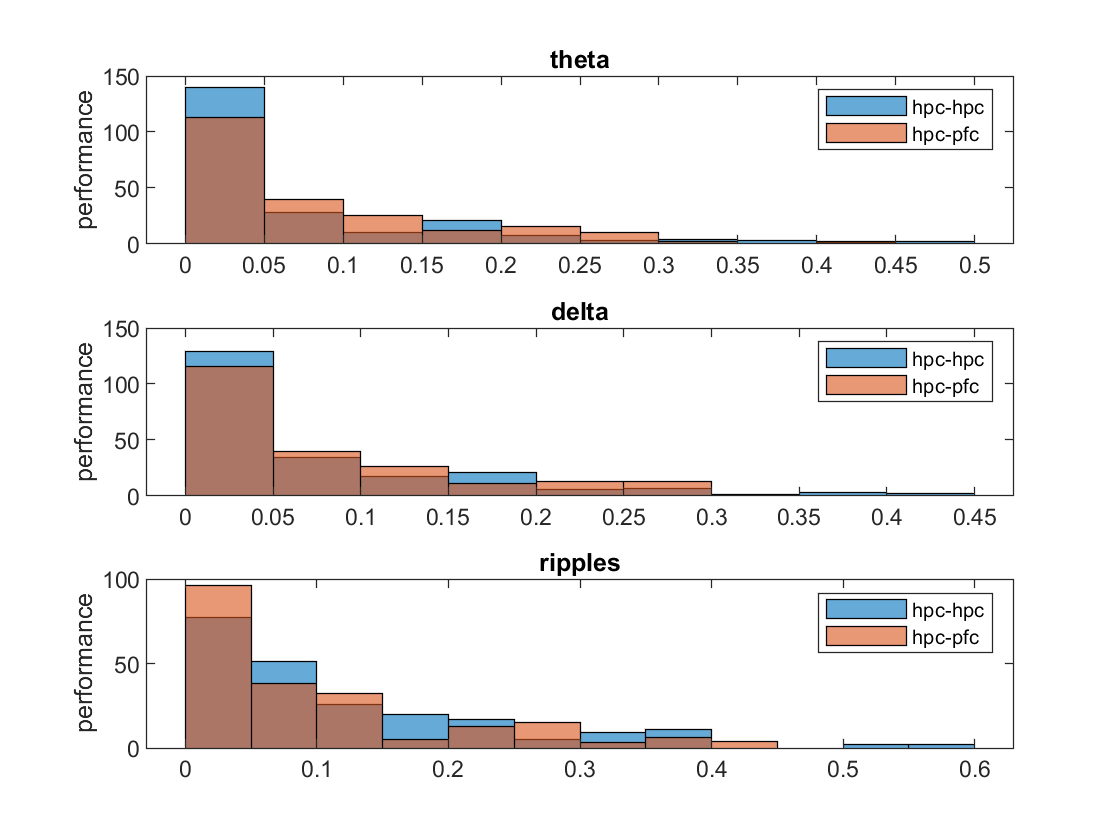

figure(233)
clf
for i = 1:nPatterns
    subplot(3,1,i)
    histogram(r_square_hh_patterns(i,:));
    hold on
    histogram(r_square_hp_patterns(i,:));
    ylabel("performance")
    title(patternnames(i));
    legend("hpc-hpc","hpc-pfc")
end


mean_hh = mean(r_square_hh(~isinf(r_square_hh)));
std_hh  = std(r_square_hh(~isinf(r_square_hh)));

mean_hp = mean(r_square_hp(~isinf(r_square_hp)));
std_hp = std(r_square_hp(~isinf(r_square_hp)));

subplot(2,1,1)
ax1 = nexttile;
hist_hh = histogram(r_square_hh,25)

hist_hh =   Histogram with properties:

             Data: [1×660 double]
           Values: [165 161 84 38 28 19 32 30 19 16 13 6 8 7 4 9 8 4 1 2 1 1 1 1 2]
          NumBins: 25
         BinEdges: [0 0.0228 0.0456 0.0684 0.0912 0.1140 0.1368 0.1596 0.1824 0.2052 0.2280 0.2508 0.2736 0.2964 0.3192 0.3420 0.3648 0.3876 0.4104 0.4332 0.4560 0.4788 0.5016 0.5244 0.5472 0.5700]
         BinWidth: 0.0228
        BinLimits: [0 0.5700]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


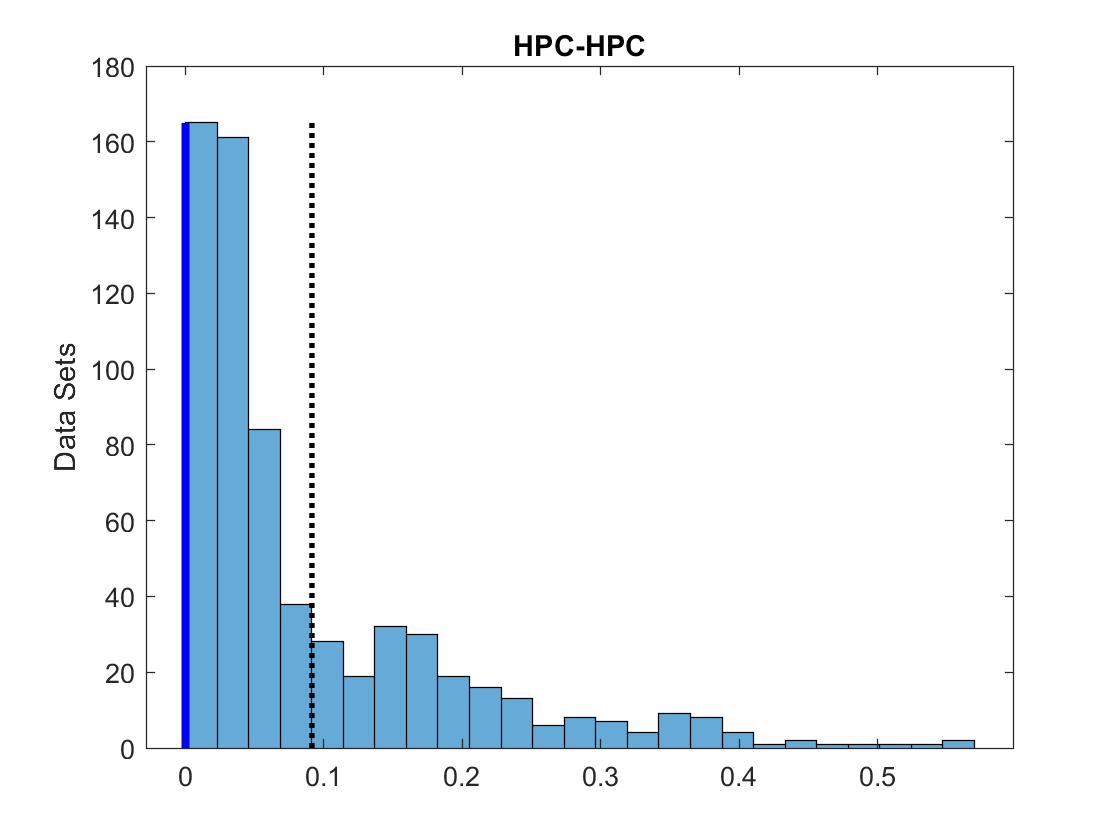

ylabel("Data Sets")
title ("HPC-HPC")
lineObject=line([mean_hh,mean_hh],[0 max(hist_hh.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
if useSinglePrediction
    lineObject2 = line([median_singlehh,median_singlehh],[0 max(hist_hh.Values)]);
    lineObject2.LineWidth = 3;
    lineObject2.Color = 'blue';
end


subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(r_square_hp,25)

hist_hp =   Histogram with properties:

             Data: [1×660 double]
           Values: [146 124 64 47 46 28 37 17 20 10 13 17 16 10 22 14 3 2 3 2 3 1 3 3 1]
          NumBins: 25
         BinEdges: [0 0.0178 0.0356 0.0534 0.0712 0.0890 0.1068 0.1246 0.1424 0.1602 0.1780 0.1958 0.2136 0.2314 0.2492 0.2670 0.2848 0.3026 0.3204 0.3382 0.3560 0.3738 0.3916 0.4094 0.4272 0.4450]
         BinWidth: 0.0178
        BinLimits: [0 0.4450]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


% prediction performance from hpc to pfc cells
ylabel("Data Sets")
title ("HPC-PFC")
xlabel("Performance")
linkaxes([ax1,ax2],'x');

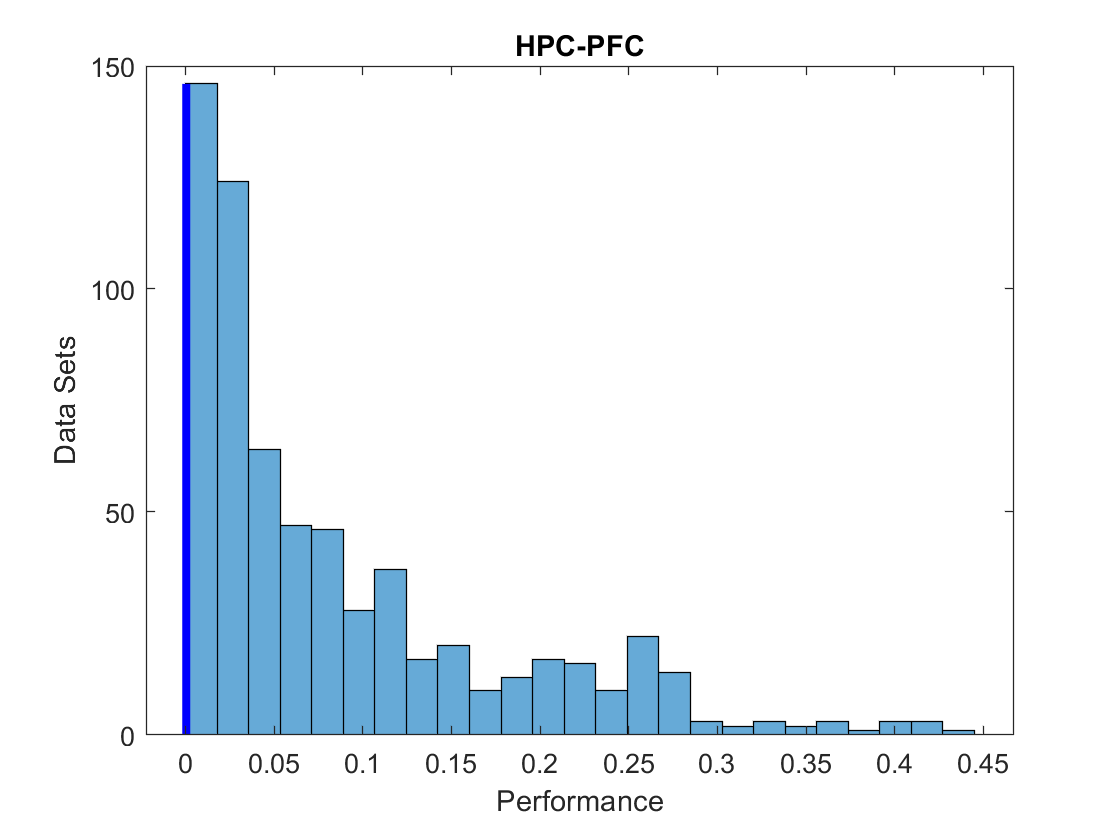

lineObject=line([mean_hp,mean_hp],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
if usingSingleprediction
    lineObject2 = line([median_singlehp,median_singlehp],[0 max(hist_hp.Values)]);
    lineObject2.LineWidth = 3;  % Thicken the line
    lineObject2.Color = 'blue'; % Color it black
end

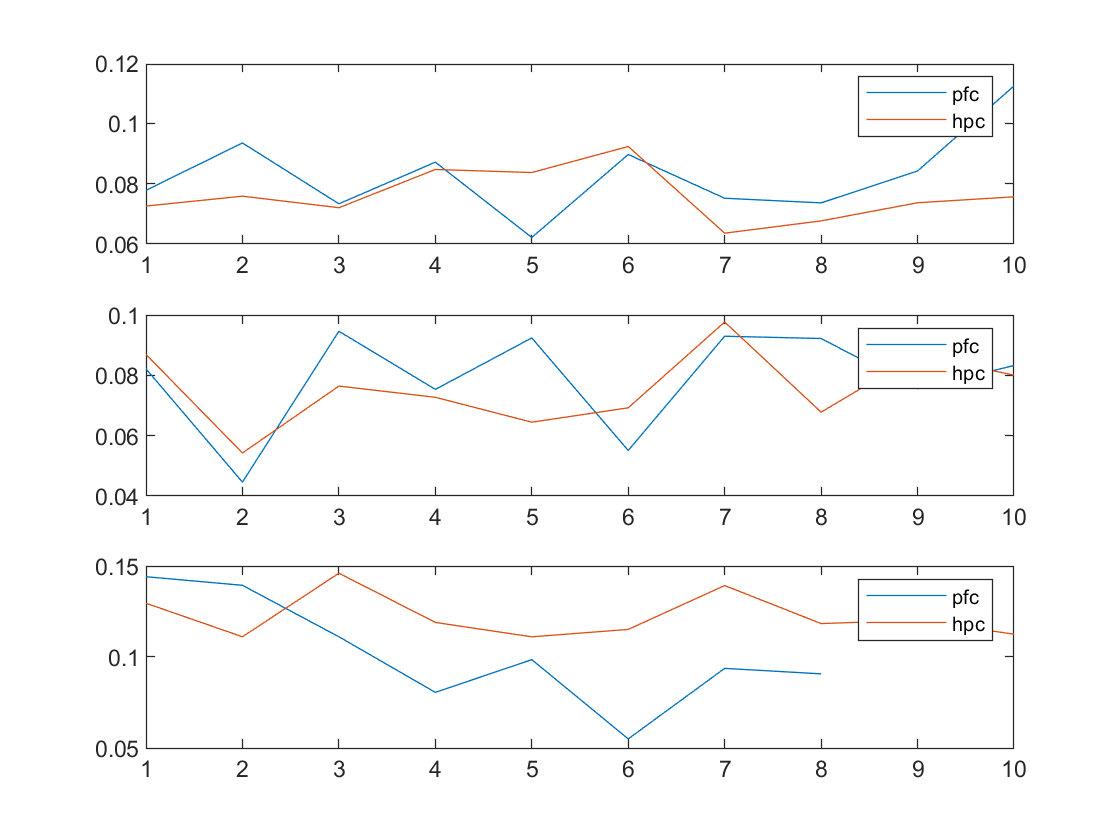

figure(601)
clf
for i = 1:nPatterns
subplot(3,1,i)
plot(patternPerformance_pfc(i,:));
hold on
plot(patternPerformance_hpc(i,:));

legend("pfc","hpc")
% how to interpret nans
end


% saving meaningful stats and the corresponding Option fields in a csv
Predictiontable  = table(mean_hh, std_hh, mean_hp, std_hp)

Predictiontable = 1×4 table
    mean_hh     std_hh     mean_hp    std_hp
    ________    _______    _______    ______

    0.091348    0.10189      NaN       NaN  


predictionRow = table(Options, Predictiontable, key)

predictionRow = 1×3 table
      Options                   Predictiontable                    key   
                    mean_hh     std_hh     mean_hp    std_hp             
    ____________    ________________________________________    _________

    [1×10 table]    0.091348    0.10189      NaN       NaN      "326c076"


predictionstats = [predictionstats; predictionRow];
save('prediction','predictionstats');


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";
disp("Prediction Performance on Average")

Prediction Performance on Average


sprintf(formatSpec1,Patterns(1,1).directionality,mean_hh,std_hh)

ans = "hpc-hpc: 0.091±0.102"

sprintf(formatSpec1,Patterns(2,1).directionality,mean_hp,std_hp)

ans = "hpc-hpc: NaN±NaN"

if useSinglePrediction
    disp('single source prediction median')
    formatSpec2 = "%s: %0.5e";
    sprintf(formatSpec2,Patterns(1,1).directionality,median_singlehh)
    sprintf(formatSpec2,Patterns(1,2).directionality,median_singlehp)
    
end

single source prediction median


ans = "hpc-hpc: -5.32686e-06"

ans = "hpc-pfc: 4.57062e-04"

## Figure 4

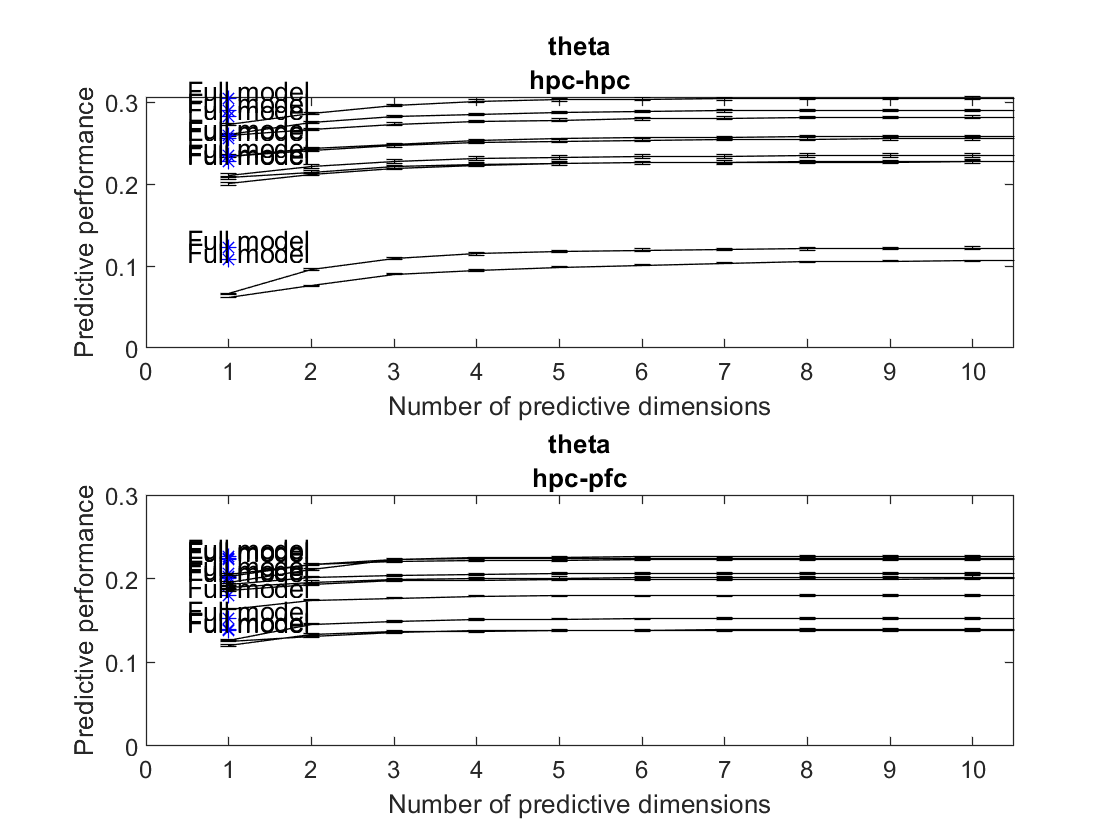

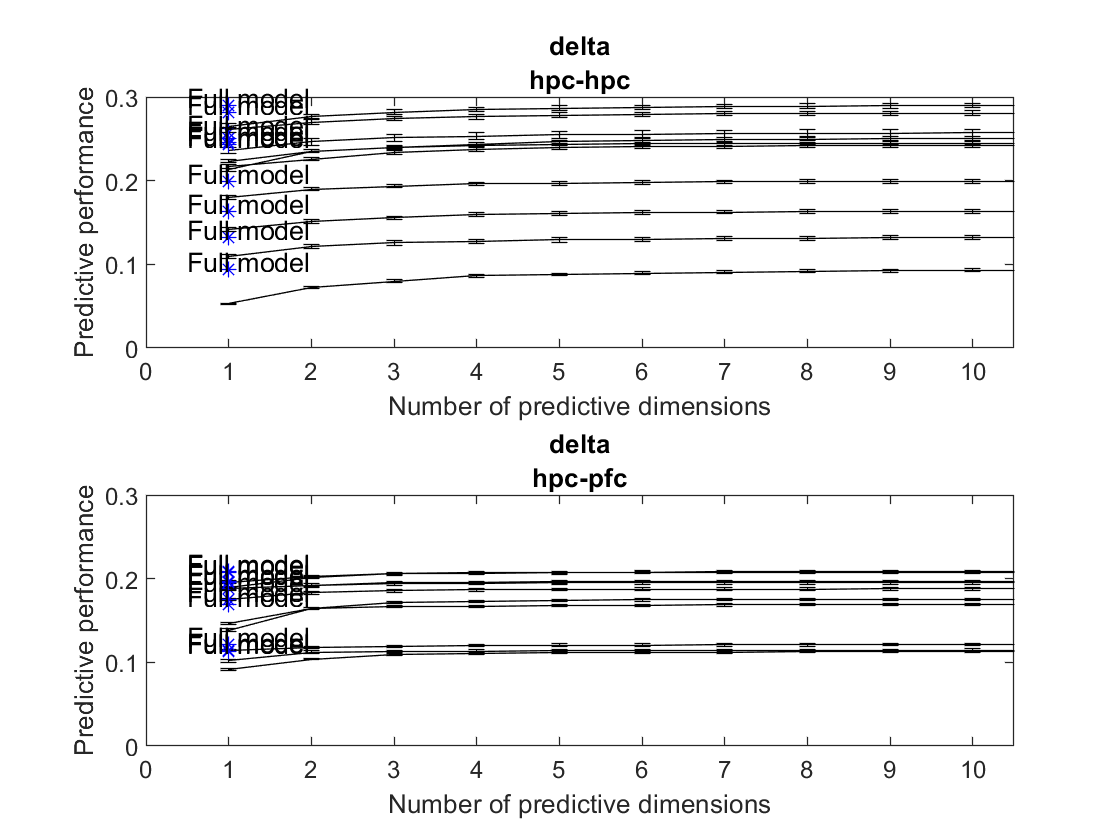

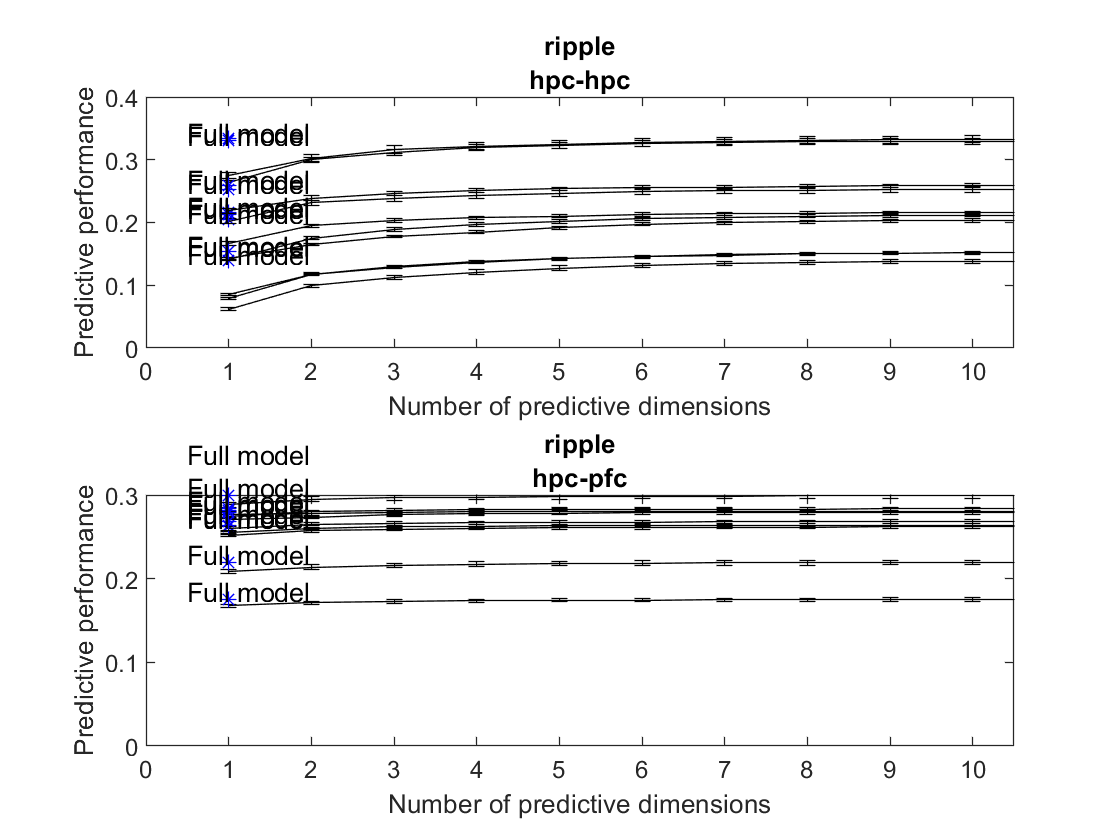

numUsedForPrediction = size(curr_target, 2);
% make the averaged version
for p = 1:10
    for i = 1:nPatterns
        figure(700+i)
        
        for j = 1:2
            subplot(2,1,j)
            curr_cvLoss = Patterns(p,j,i).rankRegress.cvLoss;
            
            plots.plotPredictiveDimensions(numUsedForPrediction,curr_cvLoss);
            
            
            title([Patterns(p,j,i).name Patterns(p,j,i).directionality])
            xlim([0,10.5])
            
            hold on
            full_model = 1-curr_cvLoss(1,end);
            plot(1, full_model,'b*');
            text(0.5, full_model+0.01, "Full model")
            
        end
        hold on
        ylim([0 0.3])
    end
end

#### 4C

#### How optimal number of predicitive dimensions compare between hpc and pfc (this is gathered over animals)

result = plots.getInfoEachOptionTuple(TABLE, "winSize", 0.3, "generateH", "fromSpectral_fromRipTimes")
numResultsToExamine = size(result,1);
ratios = zeros(3,numResultsToExamine);
hpcDims = zeros(3,numResultsToExamine);
pfcDims = zeros(3,numResultsToExamine);

for i = 1:numResultsToExamine
    currPatterns = table2array(table2array(result(i,2)));
    currPatterns = reshape(currPatterns, [10,2,4]);
    
    temp1 = zeros(3,nPartitions);
    temp2 = zeros(3,nPartitions);
    temp3 = zeros(3,nPartitions);
    for j = 1:nPartitions
        for k = 1:nPatterns
            temp2(k,j) = currPatterns(j,1,k).rankRegress.optDimReducedRankRegress;
            temp3(k,j) = currPatterns(j,2,k).rankRegress.optDimReducedRankRegress;
            temp1(k,:) = temp2(k,:)./temp3(k,:);
        end
 
    end
    
    ratios(:,i) = mean(temp1,2);
    hpcDims(:,i) = mean(temp2,2);
    pfcDims(:,i) = mean(temp3,2);
end

diff = hpcDims-pfcDims;


figure(800)

clf
for i = 1:nPatterns
    subplot(3,1,i)
    x = 1:nTarget;
    plot(x,x)
    hold on
    scatter(hpcDims(i,:), pfcDims(i,:));
    ylabel("PFC Predictive Dimensions")
    xlabel("Target HPC Predictive Dimensions")
    title(patternnames(i))
    axis square
end
